## 0. Initialize Parameters

L = 1200; % Length of bridge
n = 1200; % Discretize into 1 mm seg.
P = 400; % Total weight of train [N]
x = linspace(0, L, n+1); % x-axis

## 1. SFD, BMD under train loading

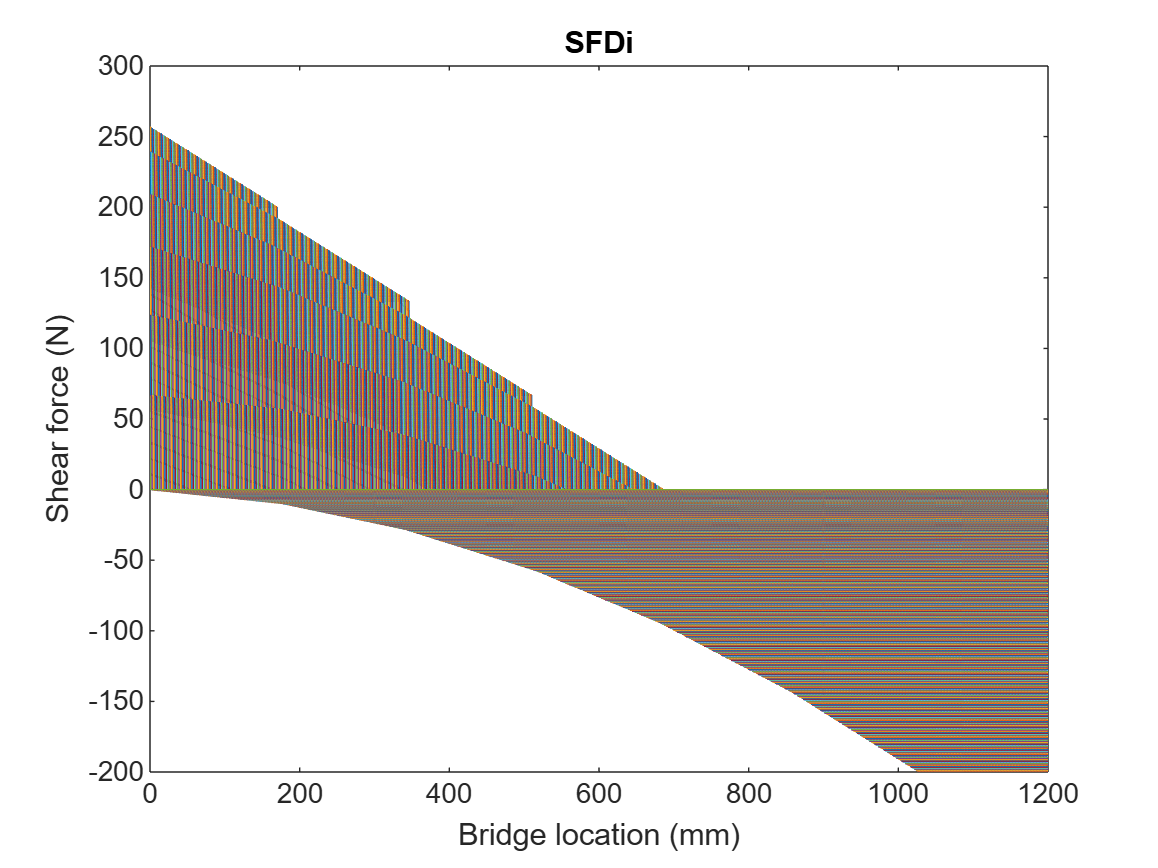

x_train = [52 228 392 568 732 908]; % Train Load Locations
x_train = x_train + 120;  % centre the train on the bridge
P_train = [1 1 1 1 1 1] * P/6;
n_train = 600; % num of train locations
SFDi = zeros(n_train, n+1); % 1 SFD for each train loc.
BMDi = zeros(n_train, n+1); % 1 BMD for each train loc.
% Solve for SFD and BMD with the train at different locations

for i = 1:n_train
    % % start location of train
    % train_pos = x_train - (n_train - i) * L / n_train
    % train_pos = x_train - (i-1)*L/(2*n_train)
    i;
    train_pos = x_train - (i-1)*x_train(end)/n_train;

    % sum of moments at A eqn
    real_train_pos = train_pos(train_pos >= 0 & train_pos <= L);
    real_P = P_train(train_pos >= 0 & train_pos <= L);
    moment_A = sum(real_train_pos.*real_P);

    % sum of Fy eqn
    By = moment_A / L;
    Ay = sum(real_P) - By;

    % construct applied loads
    % w(x)
    SFDi(i, 1) = Ay;
    next_ind = 1;
    for xi = 2:n
        SFDi(i, xi) = SFDi(i, xi-1);
        if next_ind <= length(real_P) & xi >= real_train_pos(next_ind)
            SFDi(i, xi) = SFDi(i, xi) - real_P(next_ind);
            next_ind = next_ind + 1;
        end
    end
    SFDi(i, end) = SFDi(i, end-1) + By;
    BMDi(i,:) = cumsum(-SFDi(i,:).*(L/n));
end

for i = 1:n_train
    plot(x, SFDi(i,:), DisplayName="n\_train="+i)
    hold on
end
% legend()
title("SFDi")
xlabel("Bridge location (mm)")
ylabel("Shear force (N)")
hold off

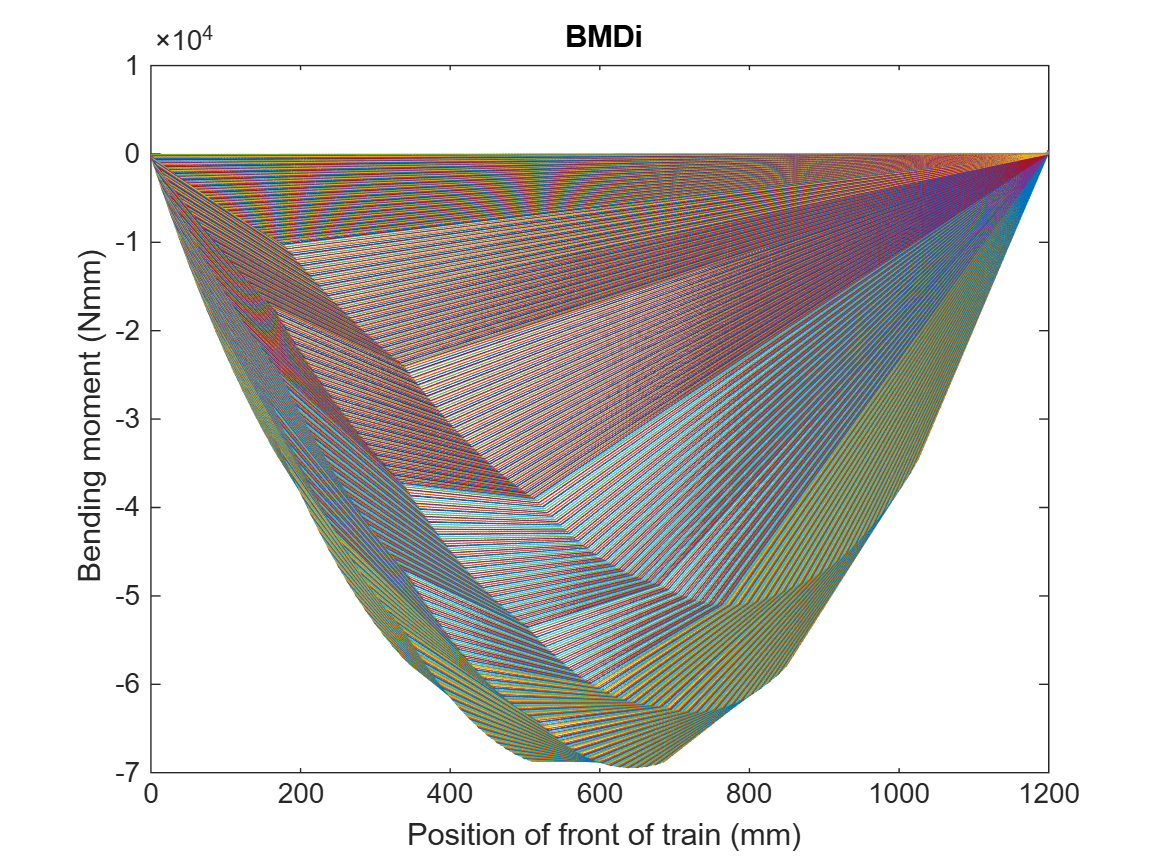


for i = 1:n_train
    plot(x, BMDi(i,:), DisplayName="n\_train="+i)
    hold on
end
% legend()
title("BMDi")
xlabel("Position of front of train (mm)")
ylabel("Bending moment (Nmm)")
hold off



SFD = max(abs(SFDi)) % SFD envelope

SFD =   257.1111  256.5400  255.9689  255.9689  255.3978  254.8267  254.8267  254.2556  254.2556  253.6844  253.1133  253.1133  252.5422  252.5422  251.9711  251.9711  251.4000  250.8289  250.8289  250.2578  250.2578  249.6867  249.1156  249.1156  248.5444  248.5444  247.9733  247.9733  247.4022  246.8311  246.8311  246.2600  246.2600  245.6889  245.1178  245.1178  244.5467  244.5467  243.9756  243.9756  243.4044  242.8333  242.8333  242.2622  242.2622  241.6911  241.1200  241.1200  240.5489  240.5489


BMD = min(BMDi) % BMD envelope

BMD = 1.0e+04 *

   -0.0257   -0.0513   -0.0768   -0.1024   -0.1277   -0.1529   -0.1784   -0.2034   -0.2288   -0.2537   -0.2784   -0.3037   -0.3283   -0.3536   -0.3780   -0.4032   -0.4274   -0.4515   -0.4766   -0.5005   -0.5255   -0.5493   -0.5730   -0.5979   -0.6214   -0.6462   -0.6695   -0.6943   -0.7175   -0.7405   -0.7652   -0.7880   -0.8127   -0.8353   -0.8579   -0.8824   -0.9048   -0.9293   -0.9515   -0.9759   -0.9980   -1.0199   -1.0442   -1.0660   -1.0902   -1.1118   -1.1333   -1.1574   -1.1787   -1.2027


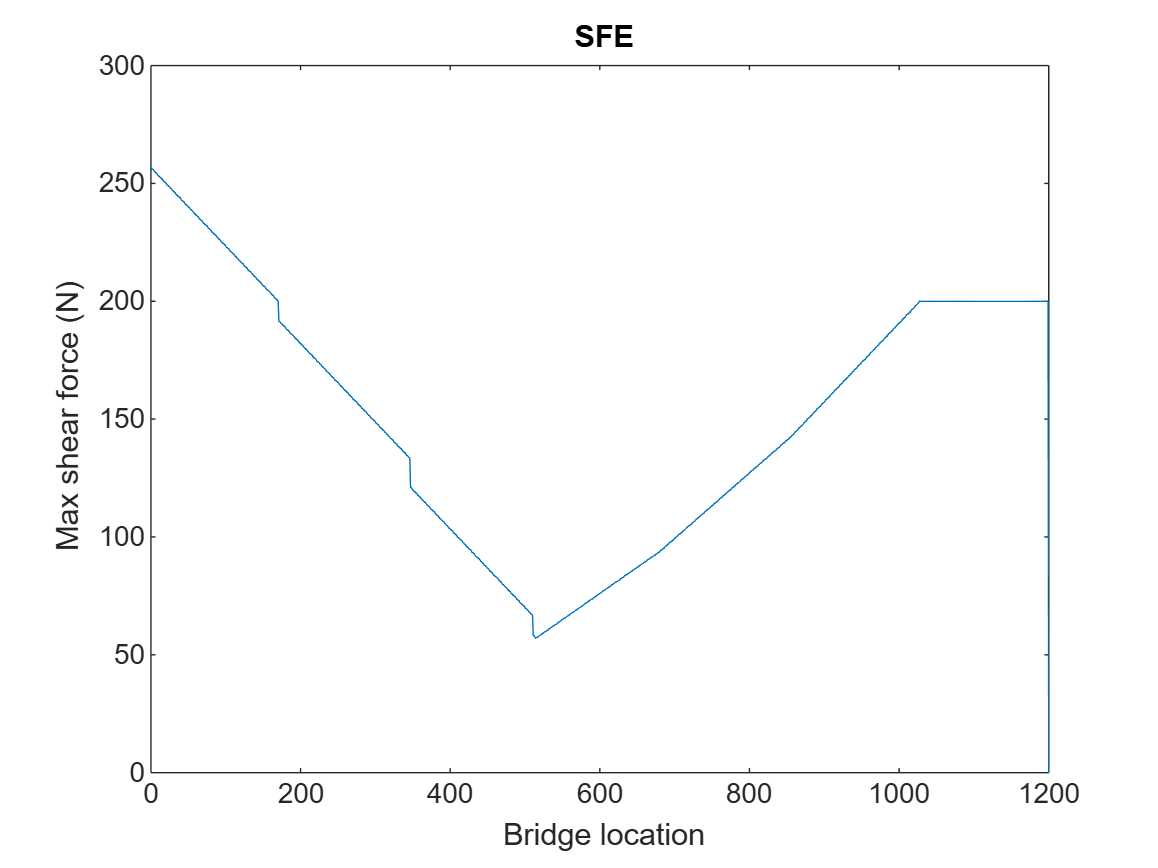


plot(x, SFD)
title("SFE")
xlabel("Bridge location")
ylabel("Max shear force (N)")

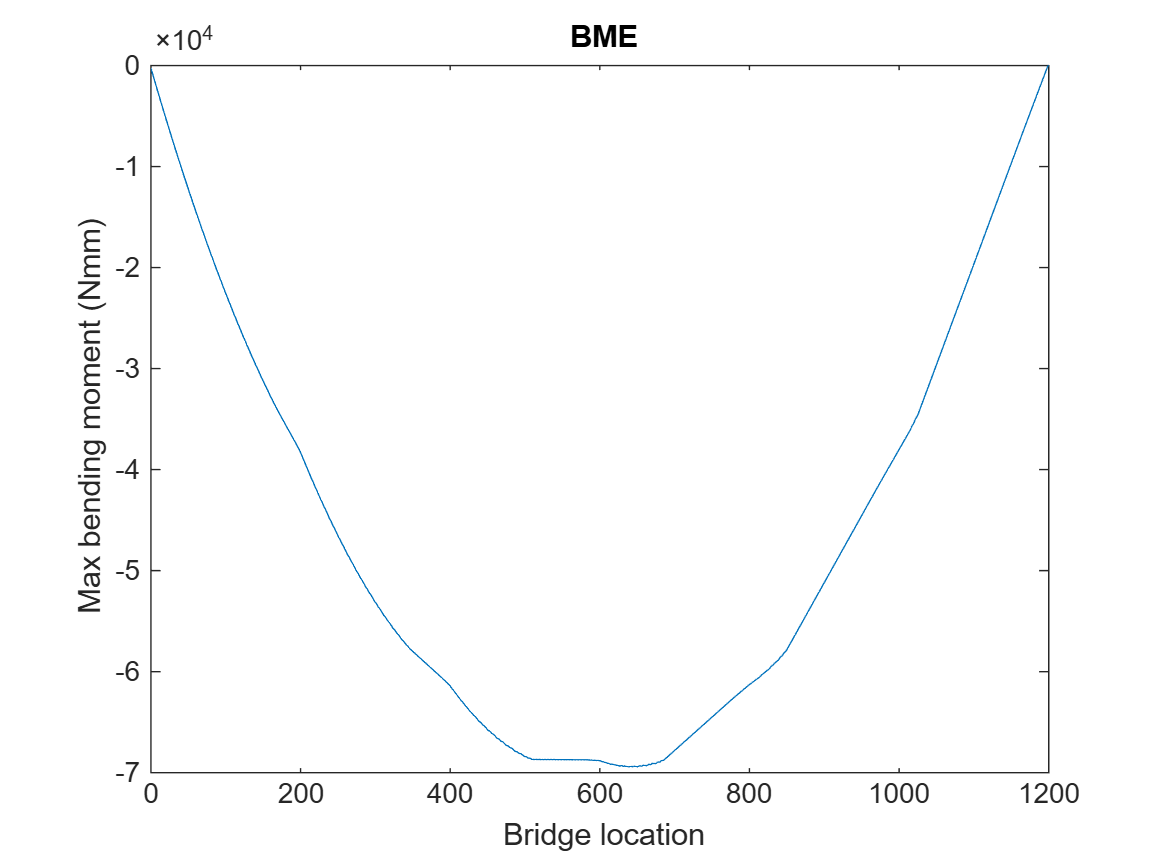


plot(x, BMD)
title("BME")
xlabel("Bridge location")
ylabel("Max bending moment (Nmm)")

## 2. Define Bridge Parameters

% = xc, bft, tft,
% param_tf = [0, 100, 1.27;
%         400, 100, 2.54;
%         800, 100, 1.27];  this is me experimenting with changing
%         cross-sections; for now we don't need this but the code is
%         written to work with changing cross-sections as well

% = x_c, b, h
param_tf = [0, 100, 1.27];
param_glue = [0, 5, 1.27];
param_side = [0, 1.27, 75];
param_bot = [0, 80-1.27*2, 1.27];

% param_tf = [0, 110, 1.27;
%             400, 110, 1.27;
%             800, 110, 1.27];
% param_glue = [0, 15, 1.27];
% param_side = [0, 1.27, 180-3.81];
% param_bot = [0, 100-1.27*2, 1.27];

%x_c Location, x, of cross-section change
%bft Top Flange Width
%tft Top Flange Thickness

% % Extracting user input assuming linear relationship
% bft = interp1(param(:,1), param(:,2), x)
% tft = interp1(param(:,1), param(:,3), x)

btf = zeros(1, n+1);
ttf = zeros(1, n+1);
bglue = zeros(1, n+1);
hglue = zeros(1, n+1);
bside = zeros(1, n+1);
hside = zeros(1, n+1);
bbot = zeros(1, n+1);
hbot = zeros(1, n+1);

btf(1,1) = param_tf(1,2);
ttf(1,1) = param_tf(1,3);
bglue(1,1) = param_glue(1,2);
hglue(1,1) = param_glue(1,3);
bside(1,1) = param_side(1,2);
hside(1,1) = param_side(1,3);
bbot(1,1) = param_bot(1,2);
hbot(1,1) = param_bot(1,3);

next_ind_tf = 2;
next_ind_glue = 2;
next_ind_side = 2;
next_ind_bot = 2;
for i = 2 : n+1
    btf(1, i) = btf(1, i-1);
    ttf(1, i) = ttf(1, i-1);
    bglue(1, i) = bglue(1, i-1);
    hglue(1, i) = hglue(1, i-1);
    bside(1, i) = bside(1, i-1);
    hside(1, i) = hside(1, i-1);
    bbot(1, i) = bbot(1, i-1);
    hbot(1, i) = hbot(1, i-1);

    if next_ind_tf <= length(param_tf(:,1)) & i >= param_tf(next_ind_tf, 1)
        btf(1, i) = param_tf(next_ind_tf, 2);
        ttf(1, i) = param_tf(next_ind_tf, 3);
        next_ind_tf = next_ind_tf + 1;
    end
    if next_ind_glue <= length(param_glue(:,1)) & i >= param_glue(next_ind_glue, 1)
        bglue(1, i) = param_glue(next_ind_glue, 2);
        hglue(1, i) = param_glue(next_ind_glue, 3);
        next_ind_glue = next_ind_glue + 1;
    end
    if next_ind_side <= length(param_side(:,1)) & i >= param_side(next_ind_side, 1)
        bside(1, i) = param_side(next_ind_side, 2);
        hside(1, i) = param_side(next_ind_side, 3);
        next_ind_side = next_ind_side + 1;
    end
    if next_ind_bot <= length(param_bot(:,1)) & i >= param_bot(next_ind_bot, 1)
        bbot(1, i) = param_bot(next_ind_bot, 2);
        hbot(1, i) = param_bot(next_ind_bot, 3);
        next_ind_bot = next_ind_bot + 1;
    end
end


## 3. Calculate Sectional Properties

% ybar. location of centroidal axis from the bottom

Aside = bside .* hside

Aside =    95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500


yside = hside ./ 2

yside =    37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000


Iside = bside .* (hside.^3) ./ 12

Iside = 1.0e+04 *

    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648



Abot = bbot .* hbot

Abot =    98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742


ybot = hbot ./ 2

ybot =     0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350


Ibot = bbot .* (hbot.^3) ./ 12

Ibot =    13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223



Atf = btf .* ttf

Atf =    127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127


ytf = hside + ttf./2

ytf =    75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350


Itf = btf .* (ttf.^3) ./ 12

Itf =    17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699



Aglue = bglue .* hglue

Aglue =     6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500


yglue = hside - hglue./2

yglue =    74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650


Iglue = bglue .* (hglue.^3) ./ 12

Iglue =     0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535



ybar = (2.*Aside.*yside + Abot.*ybot + Atf.*ytf + 2.*Aglue.*yglue) ./ (2.*Aside + Abot + Atf + 2.*Aglue)

ybar =    41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311


ybartotop = ttf + hside - ybar

ybartotop =    34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389



% I
I = 2.*Iside + 2.*Iglue + Itf + Ibot ...
    + 2.*Aside.*(yside-ybar).^2 + 2.*Aglue.*(yglue-ybar).^2 + Atf.*(ytf-ybar).^2 + Abot.*(ybot-ybar).^2

I = 1.0e+05 *

    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835



% Q at centroidal axes
Qcent = 2.*ybar.*bside.*ybar./2 + Abot.*(ybar-hbot./2)

Qcent = 1.0e+03 *

    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933


% Q at glue location
Qglue = Atf.*(ybartotop - ttf./2)

Qglue = 1.0e+03 *

    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439


## 4. Calculate Applied Stress

% S: sigma (flexural stress)   T: tau (shear stress)

S_top = abs(BMD).*(ybartotop)./I

S_top =     0.0214    0.0427    0.0639    0.0853    0.1063    0.1273    0.1485    0.1694    0.1906    0.2113    0.2319    0.2529    0.2734    0.2944    0.3147    0.3357    0.3559    0.3760    0.3969    0.4168    0.4377    0.4574    0.4771    0.4979    0.5174    0.5381    0.5576    0.5782    0.5975    0.6167    0.6372    0.6562    0.6768    0.6956    0.7144    0.7349    0.7535    0.7739    0.7924    0.8127    0.8311    0.8493    0.8696    0.8877    0.9079    0.9259    0.9437    0.9638    0.9816    1.0016


min(BMD)

ans = -6.9434e+04

ybartotop

ybartotop =    34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389


S_bot = abs(BMD).*ybar./I

S_bot =     0.0255    0.0508    0.0760    0.1014    0.1265    0.1514    0.1767    0.2014    0.2266    0.2512    0.2757    0.3008    0.3251    0.3501    0.3743    0.3993    0.4233    0.4471    0.4720    0.4957    0.5205    0.5440    0.5674    0.5921    0.6154    0.6400    0.6631    0.6876    0.7105    0.7333    0.7578    0.7804    0.8048    0.8273    0.8496    0.8739    0.8961    0.9203    0.9423    0.9665    0.9883    1.0100    1.0341    1.0557    1.0796    1.1010    1.1223    1.1462    1.1673    1.1911


T_cent = abs(SFD).*Qcent./(I.*(2.*bside))

T_cent =     1.4985    1.4952    1.4919    1.4919    1.4885    1.4852    1.4852    1.4819    1.4819    1.4786    1.4752    1.4752    1.4719    1.4719    1.4686    1.4686    1.4652    1.4619    1.4619    1.4586    1.4586    1.4553    1.4519    1.4519    1.4486    1.4486    1.4453    1.4453    1.4419    1.4386    1.4386    1.4353    1.4353    1.4320    1.4286    1.4286    1.4253    1.4253    1.4220    1.4220    1.4186    1.4153    1.4153    1.4120    1.4120    1.4087    1.4053    1.4053    1.4020    1.4020


max(T_cent)

ans = 1.4985

bglue = bglue+1.27

bglue =     6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700    6.2700


I

I = 1.0e+05 *

    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835


T_glue = abs(SFD).*Qglue./(I.*(2.*(bglue)))

T_glue =     0.2129    0.2124    0.2119    0.2119    0.2115    0.2110    0.2110    0.2105    0.2105    0.2101    0.2096    0.2096    0.2091    0.2091    0.2086    0.2086    0.2082    0.2077    0.2077    0.2072    0.2072    0.2067    0.2063    0.2063    0.2058    0.2058    0.2053    0.2053    0.2049    0.2044    0.2044    0.2039    0.2039    0.2034    0.2030    0.2030    0.2025    0.2025    0.2020    0.2020    0.2015    0.2011    0.2011    0.2006    0.2006    0.2001    0.1997    0.1997    0.1992    0.1992


## 5. Material and Thin Plate Buckling Capacities

E = 4000;
mu = 0.2;
S_tens = 30;
S_comp = 6;
T_max = 4;
T_gmax = 2;
S_buck1 = 4*pi^2*E/(12*(1-mu^2)) * (ttf./(bbot+2.*bside)).^2

S_buck1 =     3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546


S_buck2 = 0.425*pi^2*E/(12*(1-mu^2)) * (ttf./((btf-bbot-2.*bside)./2)).^2

S_buck2 =    23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911


S_buck3 = 6*pi^2*E/(12*(1-mu^2)) * (bside./(hside-ybar)).^2

S_buck3 =    29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301


T_buck = 5*pi^2*E/(12*(1-mu^2)) * ((bside./(hside-1.27*2)).^2 + (bside./400).^2)

T_buck =     5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364    5.4364


## 6. FOS

FOS_tens = S_tens ./ S_bot

FOS_tens = 1.0e+04 *

    0.1178    0.0590    0.0394    0.0296    0.0237    0.0198    0.0170    0.0149    0.0132    0.0119    0.0109    0.0100    0.0092    0.0086    0.0080    0.0075    0.0071    0.0067    0.0064    0.0061    0.0058    0.0055    0.0053    0.0051    0.0049    0.0047    0.0045    0.0044    0.0042    0.0041    0.0040    0.0038    0.0037    0.0036    0.0035    0.0034    0.0033    0.0033    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0027    0.0026    0.0026    0.0025


FOS_comp = S_comp ./ abs(S_top)

FOS_comp = 1.0e+04 *

    0.0280    0.0140    0.0094    0.0070    0.0056    0.0047    0.0040    0.0035    0.0031    0.0028    0.0026    0.0024    0.0022    0.0020    0.0019    0.0018    0.0017    0.0016    0.0015    0.0014    0.0014    0.0013    0.0013    0.0012    0.0012    0.0011    0.0011    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006


FOS_shear = T_max ./ T_cent

FOS_shear = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


FOS_glue = T_gmax ./ T_glue

FOS_glue = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


FOS_buck1 = S_buck1 ./ S_top

FOS_buck1 = 1.0e+04 *

    0.0161    0.0081    0.0054    0.0041    0.0032    0.0027    0.0023    0.0020    0.0018    0.0016    0.0015    0.0014    0.0013    0.0012    0.0011    0.0010    0.0010    0.0009    0.0009    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003


FOS_buck2 = S_buck2 ./ S_top

FOS_buck2 = 1.0e+04 *

    0.1097    0.0550    0.0367    0.0276    0.0221    0.0184    0.0158    0.0139    0.0123    0.0111    0.0101    0.0093    0.0086    0.0080    0.0075    0.0070    0.0066    0.0062    0.0059    0.0056    0.0054    0.0051    0.0049    0.0047    0.0045    0.0044    0.0042    0.0041    0.0039    0.0038    0.0037    0.0036    0.0035    0.0034    0.0033    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0026    0.0026    0.0025    0.0025    0.0024    0.0024    0.0023


FOS_buck3 = S_buck3 ./ S_top

FOS_buck3 = 1.0e+04 *

    0.1375    0.0689    0.0460    0.0345    0.0277    0.0231    0.0198    0.0174    0.0154    0.0139    0.0127    0.0116    0.0108    0.0100    0.0094    0.0088    0.0083    0.0078    0.0074    0.0071    0.0067    0.0064    0.0062    0.0059    0.0057    0.0055    0.0053    0.0051    0.0049    0.0048    0.0046    0.0045    0.0043    0.0042    0.0041    0.0040    0.0039    0.0038    0.0037    0.0036    0.0035    0.0035    0.0034    0.0033    0.0032    0.0032    0.0031    0.0031    0.0030    0.0029


FOS_buckV = T_buck ./ T_cent

FOS_buckV = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


 
FOS_tensmin = min(FOS_tens)

FOS_tensmin = 4.3628

FOS_compmin = min(FOS_comp)

FOS_compmin = 1.0377

FOS_shearmin = min(FOS_shear)

FOS_shearmin = 2.6693

FOS_gluemin = min(FOS_glue)

FOS_gluemin = 9.3944

FOS_buck1min = min(FOS_buck1)

FOS_buck1min = 0.5974

FOS_buck2min = min(FOS_buck2)

FOS_buck2min = 4.0626

FOS_buck3min = min(FOS_buck3)

FOS_buck3min = 5.0897

FOS_buckVmin = min(FOS_buckV)

FOS_buckVmin = 3.6278


% FOS_tens = S_tens / max(S_bot)
% FOS_comp = S_comp / max(S_top)
% FOS_shear = T_max / max(T_cent)
% FOS_glue = T_gmax / max(T_glue)
% FOS_buck1 = S_comp / max(S_buck1)
% FOS_buck2 = S_comp / max(S_buck2)
% FOS_buck3 = S_comp / max(S_buck3)
% 
% FOS_buckV = min(min(T_max, min(T_buck))) / max(T_cent)
% 
% FOS_buckV = zeros(1, length(T_buck))
% for i = 1:length(T_buck)
%     if T_buck(1, i) < T_max
%         FOS_buckV(1, i) = T_buck(1, i)/T_cent(1, i);
%     else
%         FOS_buckV(1, i) = T_max/T_cent(1, i);
%     end
% end
% FOS_buckVmin = min(FOS_buckV)



## 7. Min FOS and the failure load Pfail

minFOS = min([FOS_tens, FOS_comp, FOS_shear, FOS_glue, FOS_buck1, FOS_buck2, FOS_buck3, FOS_buckV])

minFOS = 0.5974

Pf = minFOS*P

Pf = 238.9781

## 8. Vfail and Mfail

Mf_tens = FOS_tens.*BMD

Mf_tens = 1.0e+05 *

   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293   -3.0293


Mf_comp = FOS_comp.*BMD

Mf_comp = 1.0e+04 *

   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049   -7.2049


Vf_shear = FOS_shear.*SFD

Vf_shear =   686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013


Vf_glue = FOS_glue.*SFD

Vf_glue = 1.0e+03 *

    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154    2.4154


Mf_buck1 = FOS_buck1.*BMD

Mf_buck1 = 1.0e+04 *

   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483   -4.1483


Mf_buck2 = FOS_buck2.*BMD

Mf_buck2 = 1.0e+05 *

   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209   -2.8209


Mf_buck3 = FOS_buck3.*BMD

Mf_buck3 = 1.0e+05 *

   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340   -3.5340


Vf_buckV = FOS_buckV.*SFD

Vf_buckV =   932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506  932.7506



% Mf_tens = -S_tens.*I./ybar
% Mf_comp = -S_comp.*I./ybartotop
% Vf_shear = T_max.*I.*2.*bside ./ Qcent;
% Vf_glue = T_gmax.*I.*2.*bglue ./ Qglue;
% Mf_buck1 = -S_buck1.*I./ ybartotop;
% Mf_buck2 = -S_buck2.*I./ ybartotop;
% Mf_buck3 = -S_buck3.*I./ ybartotop; % not sure about ybartotop here
% Vf_buckV = min(T_max, T_buck).*I.*bside ./ Qcent

## 9. Output plots of Vfail and Mfail

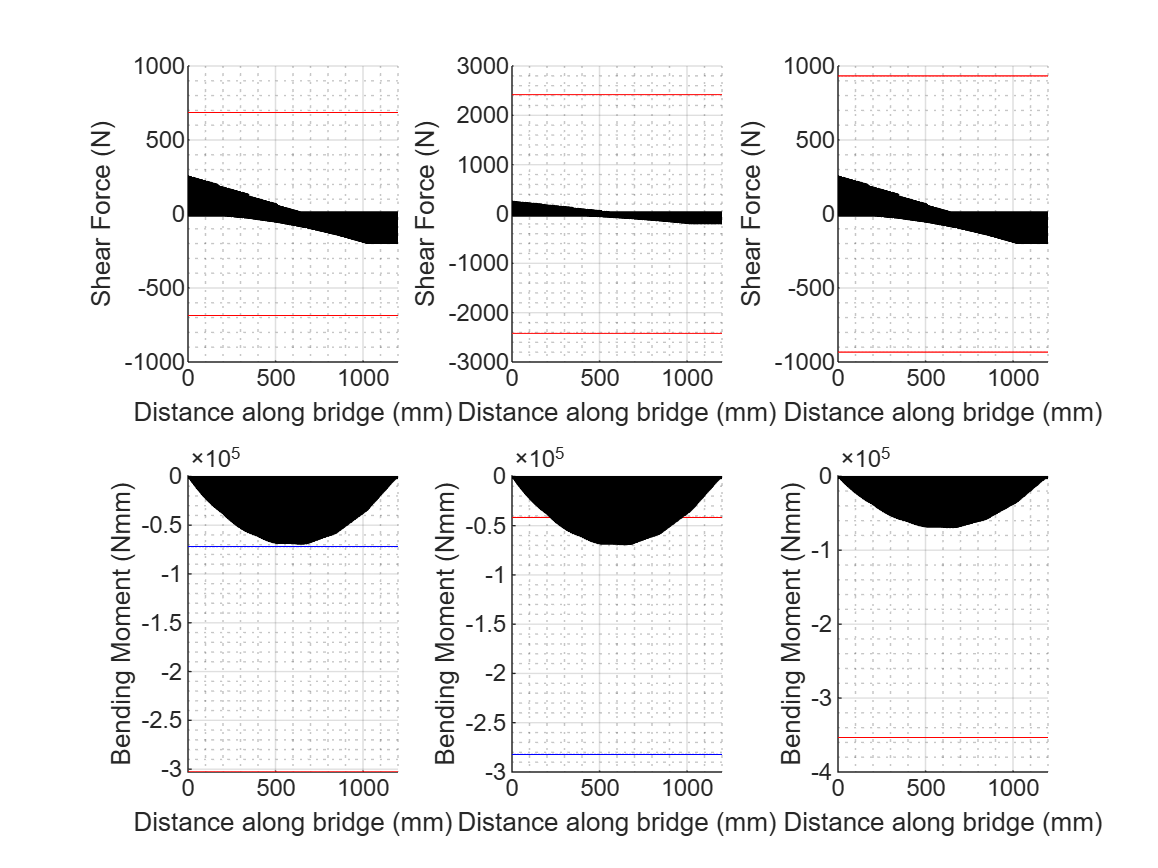

subplot(2,3,1)
hold on; grid on; grid minor;
plot(x, Vf_shear, 'r')
plot(x, -Vf_shear, 'r')
plot(x, SFDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Shear Failure')
xlabel('Distance along bridge (mm)')
ylabel('Shear Force (N)')

subplot(2,3,2)
hold on; grid on; grid minor;
plot(x, Vf_glue, 'r')
plot(x, -Vf_glue, 'r')
plot(x, SFDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Glue Shear Failure')
xlabel('Distance along bridge (mm)')
ylabel('Shear Force (N)')

subplot(2,3,3)
hold on; grid on; grid minor;
plot(x, Vf_buckV, 'r')
plot(x, -Vf_buckV, 'r')
plot(x, SFDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Buckling Shear Failure')
xlabel('Distance along bridge (mm)')
ylabel('Shear Force (N)')

subplot(2,3,4)
hold on; grid on; grid minor;
plot(x, Mf_tens, 'r')
plot(x, Mf_comp, 'b')
plot(x, BMDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Tension Failure')
% legend('Matboard Compression Failure')
xlabel('Distance along bridge (mm)')
ylabel('Bending Moment (Nmm)')

subplot(2,3,5)
hold on; grid on; grid minor;
plot(x, Mf_buck1, 'r')
plot(x, Mf_buck2, 'b')
plot(x, BMDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Buckling Failure, Top Flange - Mid')
% legend('Matboard Buckling Failure, Top Flange - Sides')
xlabel('Distance along bridge (mm)')
ylabel('Bending Moment (Nmm)')

subplot(2,3,6)
hold on; grid on; grid minor;
plot(x, Mf_buck3, 'r')
plot(x, BMDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Buckling Failure, Webs')
xlabel('Distance along bridge (mm)')
ylabel('Bending Moment (Nmm)')